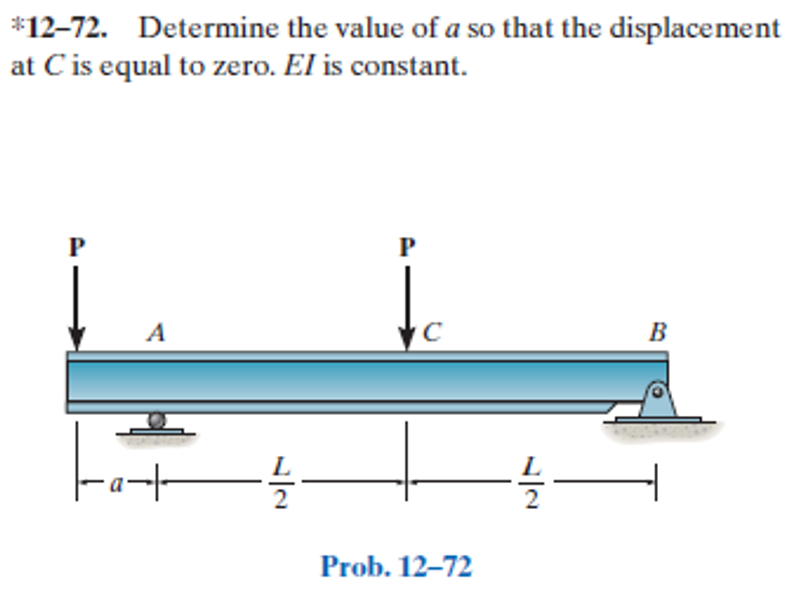

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-72P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-12-problem-72P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

P = sym('P');
a = sym('a');
L = sym('L');
new_assum = 0 < a & a < a+L/2 & a+L/2 < a+L;
assume(new_assum);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', a);
b = b.add('reaction', 'force', 'Rb', a+L);
b = b.add('concentrated', 'force', -P, 0);
b = b.add('concentrated', 'force', -P, a+L/2);
b.L = a+L;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} \frac{P\,\left(a-x\right)\,\left(3\,L^{2}-16\,L\,a-16\,a^{2}+8\,a\,x+8\,x^{2}\right)}{48\,\text{E}\,\text{I}} & \text{ if }x\leq a\\ -\frac{P\,\left(a-x\right)\,\left(-3\,L^{3}+16\,L^{2}\,a+28\,L\,a^{2}-32\,L\,a\,x+4\,L\,x^{2}+8\,a^{3}-16\,a^{2}\,x+8\,a\,x^{2}\right)}{48\,\text{E}\,\text{I}\,L} & \text{ if }a<x\wedge 2\,x\leq L+2\,a\\ \frac{P\,\left(L+a-x\right)\,\left(L^{3}+8\,L^{2}\,a-8\,L^{2}\,x-12\,L\,a^{2}+8\,L\,a\,x+4\,L\,x^{2}-8\,a^{3}+16\,a^{2}\,x-8\,a\,x^{2}\right)}{48\,\text{E}\,\text{I}\,L} & \text{ if }L+2\,a<2\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} \frac{P\,\left(-3\,L^{2}+16\,L\,a+24\,a^{2}-24\,x^{2}\right)}{48\,\text{E}\,\text{I}} & \text{ if }x\leq a\\ \frac{P\,\left(-3\,L^{3}+16\,L^{2}\,a+60\,L\,a^{2}-72\,L\,a\,x+12\,L\,x^{2}+24\,a^{3}-48\,a^{2}\,x+24\,a\,x^{2}\right)}{48\,\text{E}\,\text{I}\,L} & \text{ if }a<x\wedge 2\,x\leq L+2\,a\\ -\frac{P\,\left(9\,L^{3}+8\,L^{2}\,a-24\,L^{2}\,x-36\,L\,a^{2}+24\,L\,a\,x+12\,L\,x^{2}-24\,a^{3}+48\,a^{2}\,x-24\,a\,x^{2}\right)}{48\,\text{E}\,\text{I}\,L} & \text{ if }L+2\,a<2\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} -P\,x & \text{ if }x\leq a\\ -\frac{P\,\left(3\,L\,a-L\,x-2\,a\,x+2\,a^{2}\right)}{2\,L} & \text{ if }a<x\wedge 2\,x\leq L+2\,a\\ \frac{P\,\left(L-2\,a\right)\,\left(L+a-x\right)}{2\,L} & \text{ if }L+2\,a<2\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} -P & \text{ if }x\leq a\\ \frac{P\,\left(L+2\,a\right)}{2\,L} & \text{ if }a<x\wedge 2\,x\leq L+2\,a\\ -\frac{P\,\left(L-2\,a\right)}{2\,L} & \text{ if }L+2\,a<2\,x \end{array}\right.$$

w

$$w(x) = 0$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{P\,\left(3\,L+2\,a\right)}{2\,L}\\ \mathrm{Rb} & \frac{P\,\left(L-2\,a\right)}{2\,L} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

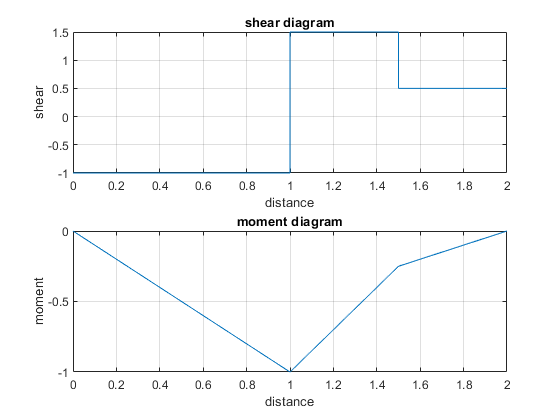

beam.shear_moment(m, v, [0 2], [P a L], 1);

# value of a that makes y at point C zero

assume([b.E b.I], 'positive');
a_yco = solve(y(a+L/2) == 0, a)

$$a\_yco = \frac{L}{3}$$

# clean up

addvar(y);
setassum(new_assum, 'clear');